# Common PID tuning rules

This file summarises a few common PID tuning rules and compares the resulting closed-loop behaviour on a number of examples. Standard tuning methods characterise the system based on a step response or critical gain and use observations taken from these to select the PID parameters. This file gives some quick background on this characterisation and illustrates the corresponding tuning on a few examples.

The transfer function of the controller contains parallel connected proportional, integrating and differentiating parts.


$$M\left(s\right)=K_p +\frac{K_i }{s}+sK_d$$


We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx, closed_vs_openloop_overlay.mlx ***and ***step_responses_with_matlab.mlx. ***A more interactive file is available in the app*** pidtuningrules.mlapp.***

This live script needs the control toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by:

 J.A.Rossiter, University of Sheffield                         

Ruth Bars, Budapest University of Technology and Economics                    

Antonio Visioli, Universita di Brescia 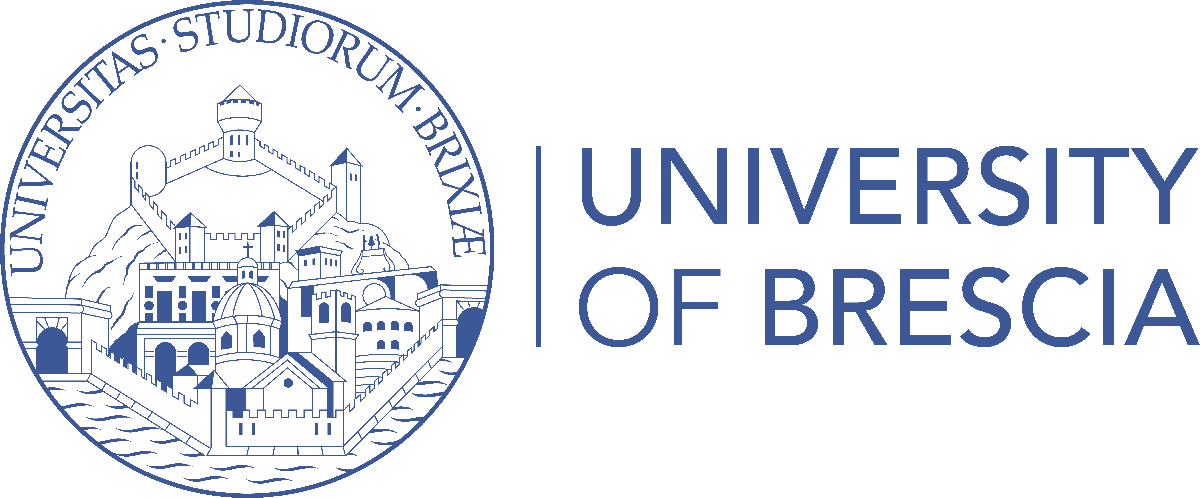

Sebastian Dormido, Universidad Nacional de Educacion a Distancia  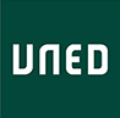

### Useful background reading

- Astrom, Karl J., Hagglund, Tore., 2006, Advanced PID Control, ISA, The Instrumentation, Systems and Automation Society. ISBN: 978155617-9426

- Aström and Hagglund, 2004, Revisiting the Ziegler-Nichols step response method for PID control, J. of Process Control 14, 635-650.

- Büchi, R., 2022, Parameter tables for PID controllers for time delayed systems optimized with a learning method, ASIM Proceedings.

- Cohen, G.H. and Coon, G.A., 1953, Theoretical consideration of retarded control, Transactions of ASAME,75, 827–834.

- Hagglund, T., 2019, The one-third rule for PI controller tuning, Computers & Chemical Engineering 127, 25-30.

- Skogestad, S., 2003, Simple analytic rules for model reduction and PIDcontroller tuning, J. of Process Control 13, 635-650.

- Svrcek, William Y., Mahoney, Donald P., Young, Brent R., 2000, A Real Time Approach to Process Control, 2nd Edition. John Wiley & Sons, Ltd. Print ISBN:9780470025338 |Online ISBN:9780470029558 |DOI:10.1002/9780470029558

- Veronesi, M. and Antonio Visioli, V., 2020, On the Selection of Lambda in Lambda Tuning for PI(D) Controllers, IFAC-PapersOnLine, 53, 2, Pages 4599-4604

## Table of contents

- Context and assumptions

- Characterising the open-loop response

- Critical gain methods

- Reaction curve methods

- PID tuning using automated methods

- Plotting of closed-loop behaviour

- Useful subfunctions

## 1. Context and assumptions

The block diagram of a control system is given in the following figure.

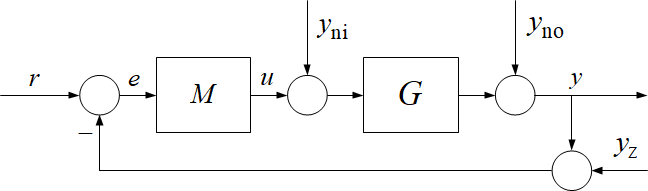

G denotes the transfer function of the model of the plant (system) to be controlled, M is the transfer function of the controller,  r denotes the reference signal, y is the output signal, u is the control signal, yni, yno and yz denote the input disturbance, the output disturbance and the measurement noise, respectively.

The aim is to design the controller parameters to fulfil the quality specifications set for the closed loop control system; her the focus is on PID designs, that is, proportional, integral and derivative. It is possible to use frequency domain methods (e.g. ***PID_Cont_Controller_Design_with_Pole_Cancellation***) but these approaches are not discussed here. Instead the focus here is on time domain approaches.

The methods given below give a starting point for the PID design, but in practice it is necessary to refine the values of the controller parameters as the 'auto-tuned' control system may not meet the specifications because of system/model mismatch, disturbances, and more.  A simplistic or approximate structure of the model of the system is supposed (e.g. first order lag with dead time), its parameters are determined approximately by measurements, and the parameters of the PID controller are fitted to the model using experimental rules. 

Define the PID compensator (controller) in parallel form as follows:

$M\left(s\right)=K_p +\frac{K_i }{s}+sK_d$;   $K_i =\frac{K_p }{T_i }$

As the ideal differentiating term is not realisable, it can be extended by a first order lag. For example

$sK_d =K_d s\frac{1}{1+\textrm{sT}}=K_p \left(\frac{sT_d }{1+s\frac{T_d }{N}}\right)$  where* N>1*. 

## 2. Characterising the open-loop response

The first thing to do is to characterise the open-loop system step response using some set parameterisation techniques. Two techniques are common.

- Find the critical gain, that is the gain which will make the system unstable with unity negative feedback. This reduces to the gain margin. Also find the associated frequency of oscillation.

- Do a step response and estimate parameters which capture this, so: i) implicit delay; ii) rise time;  iii) settling time;  iv) steady-state gain.

The following will demonstrate these characterisations although it should be emphasised that these are approximate as there is some subjectivity in the values selected.

## 3. Critical gain methods

These only work for cases where the root-loci is gauranteed to enter the RHP (which is true for real systems, but not for low order transfer functions). Also, in practice one would never do this on a real system (that is make it oscillate by pushing up the gain) so it only makes sense if one already has a model which can be used to estimate the critical gain ***K*** analytically.

**Remark**: In effect the critical gain can be determined as the gain margin, with the associated frequency being the phase cross-over frequency. Define the period of oscillation using:


$$T_p =\frac{2\pi }{w}$$


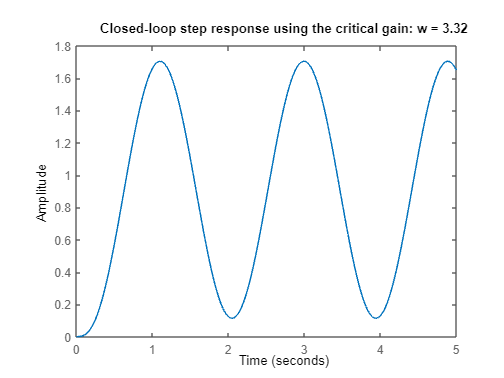

G=tf(1,[1 6 11 6]);
[gm,pm,wcp,wcg] = margin(G);
figure; clf
step(feedback(G*gm,1),5)
title(['Closed-loop step response using the critical gain: w = ',num2str(round(wcp,2))])

The critical gain and the corresponding frequency provide data for the tuning of the PID controller paraneters.

## 4. Reaction curve methods

The aim is to determine some core characteristics.

- What is the effective delay 'L' before the system starts to move, in the correct direction, in a meaningful fashion?

- At the point of maximum gradient, how long 'T' does the response take to move from 'zero' to the steady-state? Alternatively this can be viewed as something like the 63% point, that is, how long does it take to get to about 63% of the steady-state?

- What is the steady-state gain 'K'?

We use a number of different examples to show the estimation of these values, noting that it is an estimation. One cannot determine these with any objective precision. For simplicity we use a unit step response, that is the input is one.

### 4.1 1st order model with delay

For the first order model, the point of maximum gradient is as soon as the system begins moving and this gradient reaches the steady-state in one time constant *T*. The actual curve reaches 63% of the steady-state value in one time constant. Thus the effective delay and time constant can be estimated easily, and of course the steady-state gain K.

disp('Section 3 below')

Section 3 below



delay=2; T=3; gain=0.8;
G=tf(gain,[T 1],'iodelay',delay)

G =
 
                0.8
  exp(-2*s) * -------
              3 s + 1
 
Continuous-time transfer function.
Model Properties


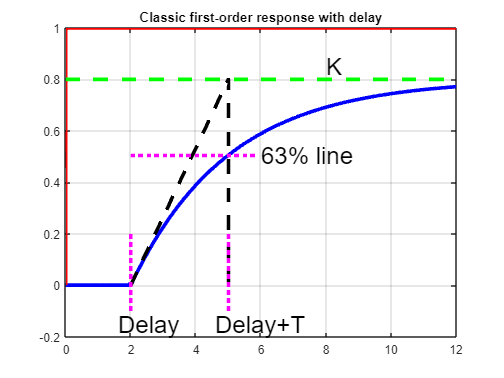

%G=tf(gain*[1 3]/3,conv([T 1],[1 1]),'iodelay',delay)
figure; clf
[y,t] = step(G,4*T);
plot(t,y,'b',[t(1),t(1),t(end)],[0 1 1],'r',[0,t(end)],[gain,gain],'g--','LineWidth',3); hold on
plot([delay,delay+T,delay+T],[0,gain,0],'k--','LineWidth',3)
plot([delay,delay],[-0.1,0.2],'m:','LineWidth',3)
text(delay-0.4,-0.15,'Delay','fontsize',20)
plot([delay,delay]+T,[-0.1,0.2],'m:','LineWidth',3)
plot([delay,delay+T*1.3],[1,1]*0.8*0.63,'m:','LineWidth',3)
text(delay+T-0.4,-0.15,'Delay+T','fontsize',20)
text(delay+1.33*T,0.63*0.8,'63% line','fontsize',20)
text(delay+2*T,0.85,'K','fontsize',20)
title('Classic first-order response with delay')
grid
hold off

**Remark**: Some higher order models behave in a similar way to 1st order models and thus the parameter estimates can be based on a similar figure.

### 4.2 High order models with slow reaction time

For higher order models, the point of maximum gradient may not be obvious, and using this to estimate* T* may or may not be easy. Alternatively, one could simply take the time the actual curve reaches 63% of the steady-state value, counting from after the implied delay. Where there is more of a lag or slow response or non-minimum phase characteristic, the estimate of the effective delay is somewhat subjective and readers need to be aware of this; using these numbers in design is always an approximation. 

disp('3rd order system below')

3rd order system below


G=tf([10],poly([-1 -2 -4]));
figure; clf
[y,t]=step(G);
plot(t,y,'linewidth',2)
L=0.4

L = 0.4000

T= 1.4

T = 1.4000

K=dcgain(G)

K = 1.2500

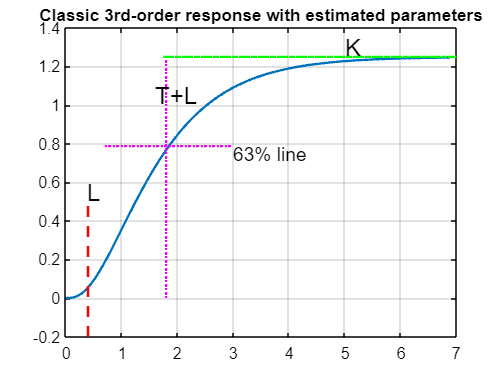

grid 
bodechange % to make figure labels bolder and larger
hold on
plot([1,1]*L,[-0.2,0.5],'r--','linewidth',2)
plot([L+0.3,3],[1,1]*0.63*K,'m:','linewidth',2)
plot([1,1]*(L+T),[-0,K],'m:','linewidth',2)
plot([1.75,7],[1,1]*K,'g-.','linewidth',2)

text(3,0.75,'63% line','fontsize',16)
text(0.38,0.55,'L','fontsize',20)
text(1.6,1.05,'T+L','fontsize',20)
text(5,1.3,'K','fontsize',20)
title('Classic 3rd-order response with estimated parameters')
hold off

### 4.3 Non-minimum phase system

With non-minimum phase systems, the effective delay takes account of the fact that we need to wait for the output to achieve the correct sign.

disp('Non-minimum phase system below')

Non-minimum phase system below


H=5*tf([-1.2 1],poly([-1 -2 -4]));
figure; clf;
[y,t]=step(H,6);
plot(t,y,'linewidth',2)
L=1.6

L = 1.6000

T= 1.05

T = 1.0500

K=dcgain(H)

K = 0.6250

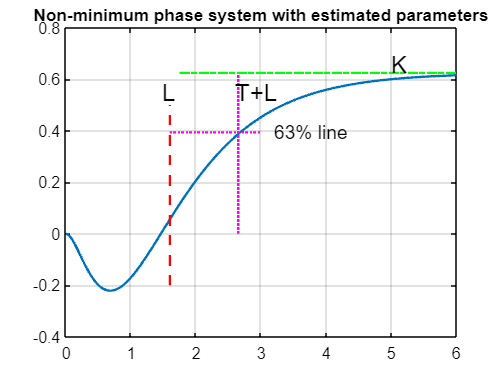

grid 
bodechange
hold on
plot([1,1]*L,[-0.2,0.5],'r--','linewidth',2)
plot([1.6,3],[1,1]*0.63*K,'m:','linewidth',2)
plot([1,1]*(L+T),[-0,K],'m:','linewidth',2)
plot([1.75,6],[1,1]*K,'g-.','linewidth',2)

text(3.2,0.4,'63% line','fontsize',16)
text(1.48,0.55,'L','fontsize',20)
text(2.6,0.55,'T+L','fontsize',20)
text(5,0.66,'K','fontsize',20)
title('Non-minimum phase system with estimated parameters')
hold off

## 5. PID tuning using automated methods

Once we have characteristed the step response in terms of the parameters: $L,T,K$then may PID tuning methods are based on these values. In essence it becomes plug and play. A sample of some popular tuning rules are given below. This list is by no means exclusive or comprehensive and we had to draw the line somewhere on how many to illustrate.

Define the PID compensator (controller) as follows:

$M\left(s\right)=K_p +\frac{K_i }{s}+sK_d$;     

**Remarks**: Some tuning rules express the integral term using an effective time constant $T_i$. In this casewe use the relationship that:

             $K_i =\frac{K_p }{T_i }$;     

Also, derivative cannot be implemented precisely and so the acutal derivative is modified as follows:           

$\;s\to \left(\frac{s\frac{K_d }{K_p }}{p\;s+1}=\frac{sT_s }{p\;s+1}\right)$   For simplicity this note uses: $p=\frac{T_d }{10}$ to ensure the filter is about a decade below the expected bandwidth.

### 4.1. Ultimate gain rules (Ziegler Nichols)

Proportional only:        	         Kp = 0.5*K		

Proportional + integral (PI):	 Kp = 0.45K	Ti = Tp/1.2	

PID:                                          Kp= 0.48K	Ti = 1.6/Tp  	Kd = Kp*Tp/10

PID (alternate)	                         Kp = 0.6K	Ti = Tp/2	        Kd = Kp*Tp/8

### 4.2 Reaction curve rules (Ziegler Nichols)

Proportional only:        	         Kp = T/KL		

Proportional + integral (PI):	 Kp = 0.9T/KL	Ki = Kp/3.33L	

PID:                                          Kp= 1.2T/KL	Ki = Kp/2L	Kd = Kp/2L

### 4.3 Cohen-Coon Method

Proportional only:        	         Kp = (1.03T/[K(L+0.34)]		

Proportional + integral (PI):	 Kp = (0.9T/[K(L+0.092)]	        Ti = 3.33L(T+0.092L)/(T+2.22L)	

PID:                                          Kp= (1.24T/[K(L+0.129)]	Ti = 2.5L(T+0.185L)/(T+0.611L)	Kd = Kp*0.37LT/(T+0.185L)

### 4.4 Skogestad method

Now the PID is written as Kc (as+1)(bs+1)/as    where:

- Kc = (1/K) (T/(L+Td)),  Td being the desired closed-loop time constant but should be greater than L.

- a = min{T,4(Td-L)}

- b = T2

- We also may need a second-order time constant T2 where clearly a 2nd order process and only if T2>L .  Otherwise  set T2=0.

- As with the other methods, a filter is added to the derivative term in the implementation of section 5.

### 4.5 Chien-Hrones-Reswick Method (Svrcek et al.)

Proportional only:                     Kp = 0.3T/LK

Proportional + integral (PI):	 Kp = 0.35T/LK	Ti = 1.2T

PID:                                          Kp= 0.6T/LK	        Ti = T	Kd = 0.5LKp	

### 4.6 AMIGO tuning rules (Astrom and Hagglund)

Proportional + integral (PI):	 Kp = 0.15/K+(0.35-(LT)/(L+T)^2)T/(KL)	   Ti = 0.35L+(6.7LT^2)/(T^2+12TL+7L^2)

PID:                                          Kp= 1/K(0.2+0.45T/L)	        Ti = (0.4L+0.8T)/(L+0.1T)L	Td = 0.5LT/(0.3L+T)

### 4.7 One-third tuning rule (Hagglund)

Proportional + integral (PI):	 Kp = 1/(3K)	Ti = L/3+T

## 5. Numerical examples

We will look at the loop responses to loop inputs of various types in order to assess the effectiveness of the different tuning rules:

- Target changes r

- Input disturbance yni

- Output disturbance yno

**NOTE: A** flat line means that the closed-loop is unstable or not-strictly proper. Where you think some lines are missing, this will be the reason.

Uncomment lines immediately below to select the desired system or indeed to enter a system of your choice. It is assumed you have done a step response such as in section 4 above to determine estimates for $L,T,K$. Note that T2 is an estimated 2nd time constant needed only for the SKOGESTAD method and Td the desired closed-loop time constant which is also used to determine the filter for the derivative term. 

This file does not interpret or evaluate the tuning methods, that is upto the user!

disp('Section 5 below here')

Section 5 below here


disp('First estimate values for L,T, K, T2 and Td')

First estimate values for L,T, K, T2 and Td


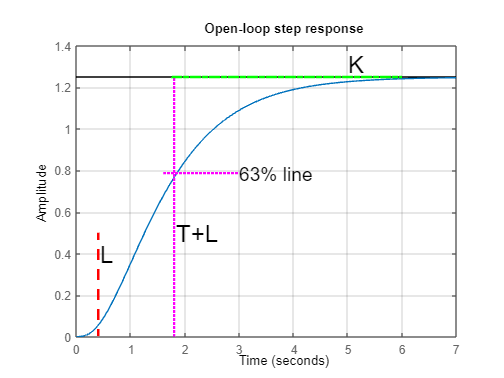

% 3rd order system
G=tf([10],poly([-1 -2 -4]));
figure; hold off
step(G); grid
title('Open-loop step response')
L=0.4; T=1.4; K=1.25;T2=0.5; Td=1;endtime=5;

% nonminiumum phase system
%H=5*tf([-1.2 1],poly([-1 -2 -4]));
% step(H); grid
%L=1.05; T=1.6; G=0.625;T2=2; Td=2; endtime=10;

hold on
plot([1,1]*L,[-0.2,0.5],'r--','linewidth',2)
plot([1.6,3],[1,1]*0.63*K,'m:','linewidth',2)
plot([1,1]*(L+T),[-0,K],'m:','linewidth',2)
plot([1.75,6],[1,1]*K,'g-.','linewidth',2)

text(T+4*L,0.63*K,'63% line','fontsize',16)
text(L*1.1,0.4,'L','fontsize',20)
text(T+L*1.1,0.4*K,'T+L','fontsize',20)
text(5,K*1.05,'K','fontsize',20)


[gm,pm,wcp,wcg] = margin(G);Kc  =gm; Tc = 2*pi/wcp;





%%%%%%% NOTE cannot do step responses to a target for PID on MATLAB as this implies differentiation of a
%%%%%%% step and thus gives unimplementable input
disp('Design and test the PID rules based on the values L, T, K, T2, Td')

Design and test the PID rules based on the values L, T, K, T2, Td



% Z-N tuning ultimate gain
Kp=Kc*0.45; Ti=Tc/1.2;
MPIZNC = tf([Kp,Kp/Ti],[1 0]);
PIZNC = findcltf(G,MPIZNC);
[yPIZNC,t] = getresponsespi(PIZNC,endtime);

Kp=Kc*0.8; Ti=Tc/2; Td=Tc/8; Kd =Kp*Td;
MPIDZNC = tf([Kp,Kp/Ti],[1 0]) + Kd*tf([10,0],[Td,10]);
PIDZNC = findcltf(G,MPIDZNC);
[yPIDZNC,t] = getresponsespid(PIDZNC,endtime);

% Z-N tuning reaction curve
Kp=0.9*T/(K*L); Ki=Kp/(3.33*L);
MPIZN = tf([Kp,Ki],[1 0]);
PIZN = findcltf(G,MPIZN);
[yPIZN,t] = getresponsespi(PIZN,endtime);

Kp=1.2*T/(K*L); Ki=Kp/(2*L); Td=0.5*L; Kd=Kp*Td;
MPIDZN = tf([Kp,Ki],[1 0]) + Kd*tf([10,0],[Td,10]);
PIDZN = findcltf(G,MPIDZN);
[yPIDZN,t] = getresponsespid(PIDZN,endtime);

%Cohen-coon tuning
Kp=(0.9*T/K)*((T/L)+0.0092)/2; Ti=3.33*L*(T+0.0092*L)/(T+2.22*L);
MPICC = tf([Kp,Kp/Ti],[1 0]);
PICC = findcltf(G,MPICC);
[yPICC,t] = getresponsespi(PICC,endtime);

Kp=(1.24*T/K)*((T/L)+0.129); Ti=2.5*L*(T+0.185*L)/(T+0.611*L); 
Td=0.37*L*T/(T+0.185*L); Kd=Kp*Td;
MPIDCC = tf([Kp,Kp/Ti],[1 0]) + Kd*tf([10,0],[Td,10]);
PIDCC = findcltf(G,MPIDCC);
[yPIDCC,t] = getresponsespid(PIDCC,endtime);

% Skogestad tuning
Kp=(1/K)*T/(L+L); Ti = min([T,4*(L+L)]); Td=T2;
MPIS = tf(Kp*[Ti,1],[Ti 0]);  %%% Poor choice if T2=0 not advised!
PIS = findcltf(G,MPIS);
[yPIS,t] = getresponsespi(PIS,endtime);

MPIDS = Kp*tf(conv([Ti,1],[Td,1]),conv([Ti 0],[Td/10 1]));
PIDS = findcltf(G,MPIDS);
[yPIDS,t] = getresponsespid(PIDS,endtime);

% Chien-Hrones-Reswick Method
Kp=(0.35*T/(L*K)); Ti=1.2*T;
MPICHR = tf([Kp,Kp/Ti],[1 0]);
PICHR = findcltf(G,MPICHR);
[yPICHR,t] = getresponsespi(PICHR,endtime);

Kp=(0.6*T/(L*K)); Ti=T; Td=0.5*L; Kd = 0.5*Td;
MPIDCHR = tf([Kp,Kp/Ti],[1 0]) + Kd*tf([10,0],[Td,10]);
PIDCHR = findcltf(G,MPIDCHR);
[yPIDCHR,t] = getresponsespid(PIDCHR,endtime);

% AMIGO Method
Kp=0.15/K+(0.35-L*T/(L+T)^2)*T/K/L; Ti=0.35*L+6.7*L*T^2/(T^2+2*L*T+10*L^2);
MPIAMIGO = tf([Kp,Kp/Ti],[1 0]);
PIAMIGO = findcltf(G,MPIAMIGO);
[yPIAMIGO,t] = getresponsespi(PIAMIGO,endtime);

Kp=1/K*(0.2+0.45*T/L); Ti=(0.4*L+0.8*T)/(L+0.1*T)*L; Td = 0.5*L*T/(0.3*L+T);
MPIDAMIGO = tf([Kp,Kp/Ti],[1 0]) + Kp*Td*tf([10,0],[Td,10]);
PIDAMIGO = findcltf(G,MPIDAMIGO);
[yPIDAMIGO,t] = getresponsespid(PIDAMIGO,endtime);

% One-third Method
Kp=1/3/K; Ti=L/3+T;
MPIOT = tf([Kp,Kp/Ti],[1 0]);
PIOT = findcltf(G,MPIOT);
[yPIOT,t] = getresponsespi(PIOT,endtime);

% lambda tuning
Kp= T/(K*(Td+L)); Ti=T;
MPIlam = tf([Kp,Kp/Ti],[1 0]);
PIlam = findcltf(G,MPIlam);
[yPIlam,t] = getresponsespi(PIlam,endtime);



%%%%%%%%%%%%% Plotting
disp('%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


disp('A plot line being constant means the TF is not proper or not stable')

A plot line being constant means the TF is not proper or not stable


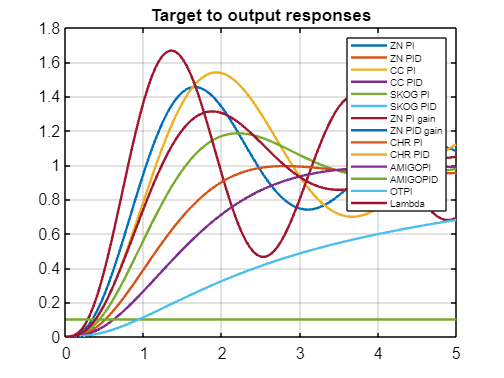

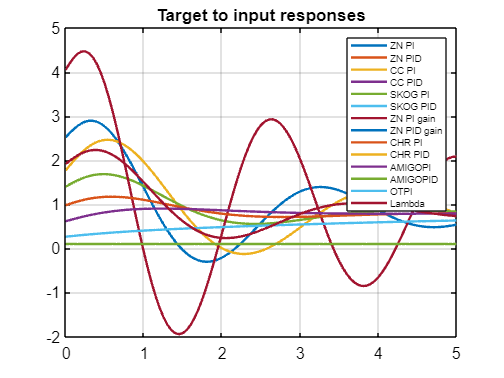

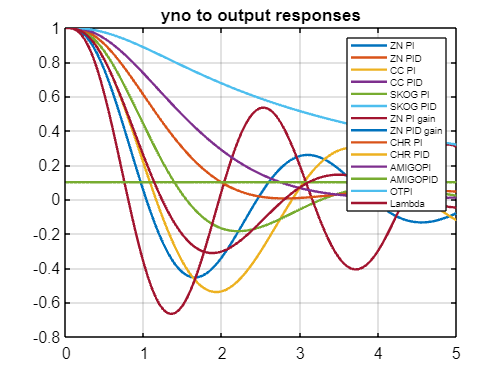

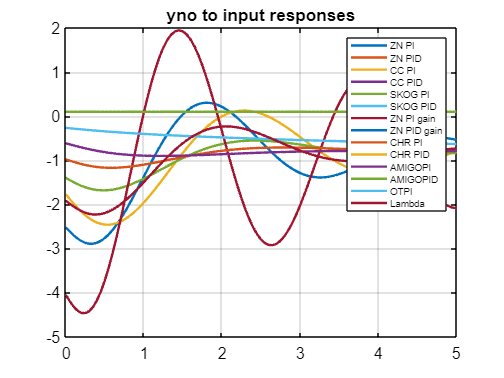

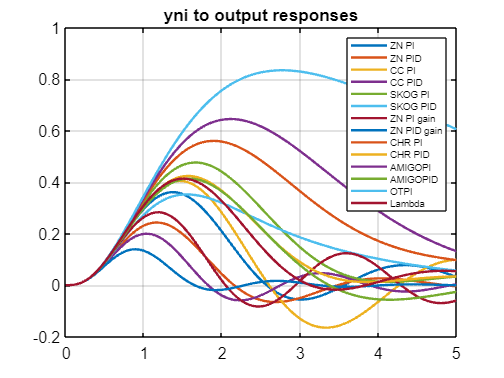

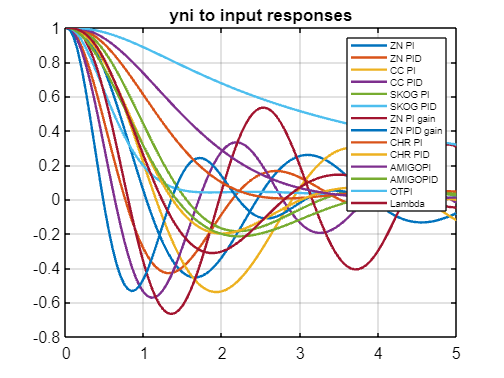


for k=1:6;
  figure; clf
    yy=plot(t,yPIZN{k},t,yPIDZN{k},t,yPICC{k},t,yPIDCC{k},t,yPIS{k},t,yPIDS{k},t,yPIZNC{k},...
        t,yPIDZNC{k},t,yPICHR{k},t,yPIDCHR{k},t,yPIAMIGO{k},t,yPIDAMIGO{k},t,yPIOT{k},t,yPIlam{k});
set(yy,'linewidth',2)
grid 
bodechange
if k==1;title('Target to output responses');
elseif k==2; title('Target to input responses');
elseif k==3; title('yno to output responses');
elseif k==4; title('yno to input responses');
elseif k==5 title('yni to output responses');
else; title('yni to input responses');
end
bb=legend('ZN PI','ZN PID', 'CC PI','CC PID','SKOG PI','SKOG PID','ZN PI gain','ZN PID gain',...
    'CHR PI','CHR PID','AMIGOPI','AMIGOPID','OTPI','Lambda'); 
set(bb,'fontsize',8);
%axis([0,6,-0.5,1.5])
end

## 6. Useful subfunctions

% Determine the closed -loop transfer functions for different loop inputs
% Determine the corresponding closed-loop responses
% The ordering should be self evident from the naming used.

 function out = findcltf(G,M)

Gc_ry=feedback(G*M,1);    % r to y
Gc_ru=feedback(M,G);      % r to u
Gc_dy=feedback(1,M*G);    % yno to y
Gc_du=-feedback(M,G);     % yno to u
Gc_duy=feedback(G,M);     % yni to y
Gc_duu=feedback(1,G*M);   % yni to u
out = cell(1);
out{1}=Gc_ry;
out{2}=Gc_ru;
out{3}=Gc_dy;
out{4}=Gc_du;
out{5}=Gc_duy;
out{6}=Gc_duu;

end

% Finds closed loop responses, iff the TF is proper and stable
function [y,t] = getresponsespi(cltf,endtime)

t = linspace(0,endtime,101);
y=cell(1);

for k=1:length(cltf);
    if and(isproper(cltf{k}),isstable(cltf{k}))
        y{k} = step(cltf{k},t);
    else
        y{k}= ones(1,101)*0.1;
    end
end

end

% Finds closed loop responses, iff the TF is proper and stable
% As this is PID, assumes that cannot be the case for responses to targets
function [y,t] = getresponsespid(cltf,endtime)

t = linspace(0,endtime,101);
y=cell(1);
y{1}=ones(1,101)*0.1;
y{2}=ones(1,101)*0.1;
y{3}=ones(1,101)*0.1;
y{4}=ones(1,101)*0.1;

for k=5:6;
    if and(isproper(cltf{k}),isstable(cltf{k}))
        y{k} = step(cltf{k},t);
    else
        y{k}= ones(1,101)*0.1;
    end
end

end

% makes figure axis and ticks bolder and larger
function bodechange

h=findobj(get(gcf, 'children'), 'Type', 'axes');

for i=1:length(h)
    set(h(i), 'fontSize', 13)
    set(h(i), 'XColor', [0 0 0])
     set(h(i), 'YColor', [0 0 0])
    
end

end

